
set_matlab_default;
takeall = 0;

if isempty(ind)
    ind = 1:length(r.Units.SpikeTimes);
    takeall = 1;
else
    if length(ind) == 2
        ind_unit = find(r.Units.SpikeNotes(:, 1)==ind(1) & r.Units.SpikeNotes(:, 2)==ind(2));
        ind = ind_unit;
    end
end
ku_all = ind; % ind is used in different places

tic
ComputeRange = [];  % this is the range where time is extracted. Event times outside of this range will be discarded. Empty means taking everything

CentInTimeDomain  = [1000 2500]; % default
CentOutTimeDomain = [1500 1000];
ChoiceTimeDomain  = [1000 2000];
TriggerTimeDomain = [1000 1500];
c_reward = [237 43 42] / 255;
ToSave = 'on';

rb = r.Behavior;
% all FPs
if length(r.BehaviorClass) > 1
    r.BehaviorClass = r.BehaviorClass{1};
end

MixedFPs = r.BehaviorClass.TargetFP; % you have to use BuildR2023 or BuildR4Tetrodes2023 to have this included in r.
MixedFPs = MixedFPs(MixedFPs>0);
nFPs     = length(MixedFPs);

Ports  = r.BehaviorClass.LeftRight;
nPorts = length(Ports);

%% Cent poke-in
ind_cent_in = find(strcmp(rb.Labels, 'PokeCentIn'));
t_cent_in = shape_it(rb.EventTimings(rb.EventMarkers==ind_cent_in));
disp(['Number of Cent poke-in is ' num2str(length(t_cent_in))])

Number of Cent poke-in is 125


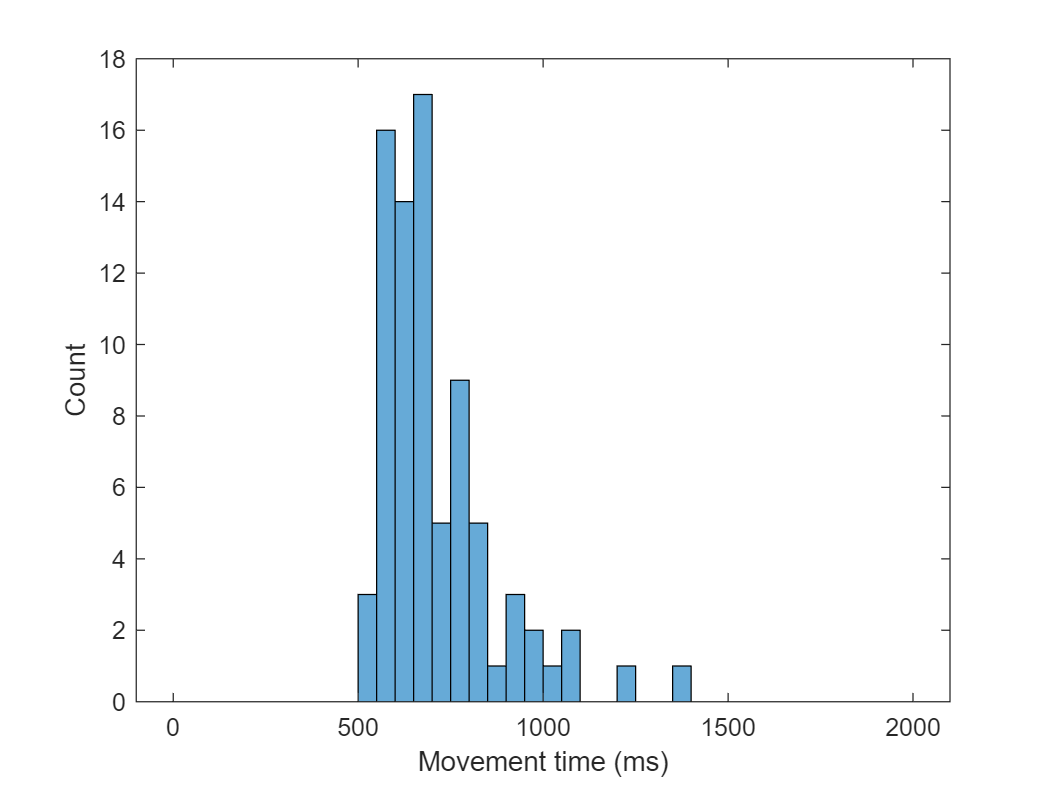

% index and time of correct cent_in
t_correct_cent_in     = t_cent_in(rb.CorrectIndex);
FPs_correct_cent_in   = shape_it(rb.Foreperiods(rb.CorrectIndex));
Ports_correct_cent_in = shape_it(rb.PortCorrect(rb.CorrectIndex));
% get correct response
t_correct_cent_in_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        t_correct_cent_in_sorted{i, j} = t_correct_cent_in(FPs_correct_cent_in==MixedFPs(i) & Ports_correct_cent_in==Ports(j));
    end
end

%% Cent poke-out
ind_cent_out       = find(strcmp(rb.Labels, 'PokeCentOut'));
t_cent_out         = shape_it(rb.EventTimings(rb.EventMarkers == ind_cent_out));
t_correct_cent_out = t_cent_out(rb.CorrectIndex);
t_correct_cent_out_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        t_correct_cent_out_sorted{i, j} = t_correct_cent_out(FPs_correct_cent_in==MixedFPs(i) & Ports_correct_cent_in==Ports(j));
    end
end
rt_correct = t_correct_cent_out - t_correct_cent_in - FPs_correct_cent_in;
% reaction time
indsort           = cell(nFPs, nPorts);
rt_correct_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        rt_correct_sorted{i, j}                  = rt_correct(FPs_correct_cent_in==MixedFPs(i) & Ports_correct_cent_in==Ports(j));
        [rt_correct_sorted{i, j}, indsort{i, j}] = sort(rt_correct_sorted{i, j});
        t_correct_cent_in_sorted{i, j}           = t_correct_cent_in_sorted{i, j}(indsort{i, j});
        t_correct_cent_out_sorted{i, j}          = t_correct_cent_out_sorted{i, j}(indsort{i, j});
    end
end

rt_cent_in_sorted  = rt_correct_sorted;
rt_cent_out_sorted = rt_correct_sorted;

%% Premature responses
ind_premature        = find(strcmp(r.Behavior.Outcome, 'Premature'));
t_cent_in_premature  = t_cent_in(ind_premature);
t_cent_out_premature = t_cent_out(ind_premature);
FPs_premature        = shape_it(rb.Foreperiods(ind_premature));
Ports_premature      = shape_it(rb.PortCorrect(ind_premature));

ind_sort = cell(nFPs, nPorts); % index of FPs and ports
t_premature_cent_in_sort  = cell(nFPs, nPorts);
t_premature_cent_out_sort = cell(nFPs, nPorts);
premature_duration        = cell(nFPs, nPorts);
indx_premature_duration   = cell(nFPs, nPorts);

t_premature_cent_in = []; % sorted version time of premature cent_in
t_premature_cent_out = []; % sorted, time of premature cent_out
premature_duration_cent_in = [];
premature_duration_cent_out = [];
FPs_premature_cent_in  = [];
FPs_premature_cent_out = [];
Ports_premature_cent_in  = [];
Ports_premature_cent_out = [];

for i = 1:nFPs
    for j = 1:nPorts
        ind_sort{i, j} = find(FPs_premature==MixedFPs(i) & Ports_premature==Ports(j));
        t_premature_cent_in_sort{i, j}  = t_cent_in_premature(ind_sort{i, j});
        t_premature_cent_out_sort{i, j} = t_cent_out_premature(ind_sort{i, j});

        premature_duration_ij = t_premature_cent_out_sort{i, j} - t_premature_cent_in_sort{i, j};
        [premature_duration{i, j}, indx_premature_duration{i, j}] = sort(premature_duration_ij);
        t_premature_cent_in_sort{i, j} = t_premature_cent_in_sort{i, j}(indx_premature_duration{i, j});
        t_premature_cent_out_sort{i, j} = t_premature_cent_out_sort{i, j}(indx_premature_duration{i, j});

        t_premature_cent_in = [t_premature_cent_in; t_premature_cent_in_sort{i, j}];
        t_premature_cent_out = [t_premature_cent_out; t_premature_cent_out_sort{i, j}];

        premature_duration_cent_in = [premature_duration_cent_in;  t_premature_cent_out_sort{i, j}-t_premature_cent_in_sort{i, j}];
        premature_duration_cent_out = [premature_duration_cent_out;  t_premature_cent_out_sort{i, j}-t_premature_cent_in_sort{i, j}];

        FPs_premature_cent_in  = [FPs_premature_cent_in; MixedFPs(i)*ones(length(ind_sort{i, j}), 1)];
        FPs_premature_cent_out = [FPs_premature_cent_out; MixedFPs(i)*ones(length(ind_sort{i, j}), 1)];

        Ports_premature_cent_in  = [Ports_premature_cent_in; Ports(j)*ones(length(ind_sort{i, j}), 1)];
        Ports_premature_cent_out = [Ports_premature_cent_out; Ports(j)*ones(length(ind_sort{i, j}), 1)];
    end
end

%% Late response
ind_late        = find(strcmp(r.Behavior.Outcome, 'Late'));
t_cent_in_late  = t_cent_in(ind_late);
t_cent_out_late = t_cent_out(ind_late);
FPs_late        = shape_it(rb.Foreperiods(ind_late));
Ports_late      = shape_it(rb.PortCorrect(ind_late));

ind_sort             = cell(1, nFPs); % index of FPs
t_late_cent_in_sort  = cell(1, nFPs);
t_late_cent_out_sort = cell(1, nFPs);
late_duration        = cell(1, nFPs);
indx_late_duration   = cell(1, nFPs);

t_late_cent_in  = []; % sorted version time of late cent_in
t_late_cent_out = []; % sorted, time of late cent_out
late_duration_cent_in  = [];
late_duration_cent_out = [];
FPs_late_cent_in  = [];
FPs_late_cent_out = [];
Ports_late_cent_in  = [];
Ports_late_cent_out = [];

for i = 1:nFPs
    for j = 1:nPorts
        ind_sort{i, j} = find(FPs_late==MixedFPs(i) & Ports_late==Ports(j));
        t_late_cent_in_sort{i, j}  = t_cent_in_late(ind_sort{i, j});
        t_late_cent_out_sort{i, j} = t_cent_out_late(ind_sort{i, j});

        late_duration_ij =  t_late_cent_out_sort{i, j} - t_late_cent_in_sort{i, j};
        [late_duration{i, j}, indx_late_duration{i, j}] = sort(late_duration_ij);
        t_late_cent_in_sort{i, j} = t_late_cent_in_sort{i, j}(indx_late_duration{i, j});
        t_late_cent_out_sort{i, j} = t_late_cent_out_sort{i, j}(indx_late_duration{i, j});

        t_late_cent_in = [t_late_cent_in; t_late_cent_in_sort{i, j}];
        t_late_cent_out = [t_late_cent_out; t_late_cent_out_sort{i, j}];

        late_duration_cent_in = [late_duration_cent_in;  t_late_cent_out_sort{i, j}-t_late_cent_in_sort{i, j}];
        late_duration_cent_out = [late_duration_cent_out;  t_late_cent_out_sort{i, j}-t_late_cent_in_sort{i, j}];

        FPs_late_cent_in  = [FPs_late_cent_in; MixedFPs(i)*ones(length(ind_sort{i, j}), 1)];
        FPs_late_cent_out = [FPs_late_cent_out; MixedFPs(i)*ones(length(ind_sort{i, j}), 1)];

        Ports_late_cent_in  = [Ports_late_cent_in; Ports(j)*ones(length(ind_sort{i, j}), 1)];
        Ports_late_cent_out = [Ports_late_cent_out; Ports(j)*ones(length(ind_sort{i, j}), 1)];
    end
end

%% Choice
ind_choice    = find(strcmp(rb.Labels, 'PokeChoiceIn'));
t_choice      = shape_it(rb.EventTimings(rb.EventMarkers==ind_choice));
move_time     = zeros(1, length(t_choice));
tmin          = 200; % allow at least 0.2 second between a successful cent_out and poke
tmax          = 2000; % allow at most 2 second between a successful cent_out and poke
t_choice_FP   = zeros(1, length(t_choice)); % find out cent_in FP associated with each reward
t_choice_Port = zeros(1, length(t_choice)); % find out cent_in FP associated with each reward

for i = 1:length(t_choice)
    dt = t_choice(i)-t_correct_cent_out;
    dt = dt(dt>tmin & dt<tmax); % reward must be collected within 2 sec after a correct cent_out
    if ~isempty(dt)
        move_time(i) = dt(end);
        % FPs_correct_cent_in
        ind = find(t_correct_cent_out==t_choice(i)-dt(end));
        if ~isempty(ind)
            %             disp(ind)
            t_choice_FP(i)   = FPs_correct_cent_in(ind);
            t_choice_Port(i) = Ports_correct_cent_in(ind);
        else
            disp('Not found')
        end
    else
        move_time(i) = NaN;
    end
end

t_choice    = t_choice(~isnan(move_time));
move_time   = move_time(~isnan(move_time));
FP_choice   = t_choice_FP(~isnan(move_time));
Port_choice = t_choice_Port(~isnan(move_time));
% Check movement time distribution
Edges = (0:50:2000);
figure(45); clf;
histogram(move_time, Edges)
xlabel('Movement time (ms)')
ylabel('Count')


% sort choice according to FP
t_choice_sorted  = cell(nFPs, nPorts);
move_time_sorted = cell(nFPs, nPorts);
for i = 1:nFPs
    for j = 1:nPorts
        ind = find(FP_choice==MixedFPs(i) & Port_choice==Ports(j));
        t_choice_sorted{i, j}  = t_choice(ind);
        move_time_sorted{i, j} = move_time(ind);
        % rank them
        [move_time_sorted{i, j}, indsort] = sort(move_time_sorted{i, j});
        t_choice_sorted{i, j} =  t_choice_sorted{i, j}(indsort);
    end
end
move_time = move_time_sorted;
t_choice = t_choice_sorted;

%% Trigger
ind_triggers = find(strcmp(rb.Labels, 'Trigger'));
t_triggers   = shape_it(rb.EventTimings(rb.EventMarkers==ind_triggers)); % trigger time in ms.

triggers_types = cell(1, length(t_triggers));
triggers_FPs   = zeros(1, length(t_triggers));
triggers_Ports = zeros(1, length(t_triggers));
triggers_RTs   = nan(1, length(t_triggers)); % reaction time (used for ranking later)

for i =1:length(t_triggers)
    it_trigger = t_triggers(i);
    % find the most recent cent_in
    ind_recent_cent_in = find(t_cent_in<it_trigger, 1, 'last');
    if ~isempty(ind_recent_cent_in) && abs(t_cent_in(ind_recent_cent_in)-it_trigger)<2500
        % check the condition
        triggers_types{i} = r.Behavior.Outcome{ind_recent_cent_in};
        triggers_FPs(i)   = r.Behavior.Foreperiods(ind_recent_cent_in);
        triggers_Ports(i) = r.Behavior.PortCorrect(ind_recent_cent_in);
        ind_following_cent_out = find(t_cent_out>it_trigger, 1, 'first');
        if ~isempty(ind_following_cent_out)
            triggers_RTs(i) = t_cent_out(ind_following_cent_out) - it_trigger;
        end
    else
        triggers_types{i} = 'NaN';
        triggers_FPs(i)   = NaN;
        triggers_Ports(i) = NaN;
    end
end

t_triggers_late = t_triggers(strcmp(triggers_types, 'Late'));
FP_triggers_late = triggers_FPs(strcmp(triggers_types, 'Late'));
triggers_RTs_late = triggers_RTs(strcmp(triggers_types, 'Late'));
[triggers_RTs_late, ind_sorted] = sort(triggers_RTs_late);
t_triggers_late = t_triggers_late(ind_sorted);
FP_triggers_late = FP_triggers_late(ind_sorted);

% trigger according to FPs
t_triggers_sort  = cell(nFPs, nPorts);
RT_triggers_sort = cell(nFPs, nPorts);

for i = 1:nFPs
    for j = 1:nPorts
        % sort trigger (to plot)
        t_triggers_sort{i, j}  = t_triggers(strcmp(triggers_types, 'Correct') & triggers_FPs==MixedFPs(i) & triggers_Ports==Ports(j));
        RT_triggers_sort{i, j} = triggers_RTs(strcmp(triggers_types, 'Correct') & triggers_FPs==MixedFPs(i) & triggers_Ports==Ports(j));
        % sort according to reaction time
        [RT_triggers_sort{i, j}, ind_sorted] = sort(RT_triggers_sort{i, j});
        t_triggers_sort{i, j} = t_triggers_sort{i, j}(ind_sorted);
    end
end

%% Check ComputeRange
if ~isempty(ComputeRange)
    t_cent_in(t_cent_in<ComputeRange(1) | t_cent_in>ComputeRange(2))=[];
    
    for i=1:nFPs
        to_remove = find(t_correct_cent_in_sorted{i}<ComputeRange(1) | t_correct_cent_in_sorted{i}>ComputeRange(2) | t_correct_cent_out_sorted{i}<ComputeRange(1) | t_correct_cent_out_sorted{i}>ComputeRange(2));
        t_correct_cent_out_sorted{i}(to_remove) = [];
        rt_cent_out_sorted{i}(to_remove)        = [];
        t_correct_cent_in_sorted{i}(to_remove)  = [];
        rt_cent_in_sorted{i}(to_remove)         = [];
    end
    to_remove_premature = find(t_premature_cent_in<ComputeRange(1) | t_premature_cent_in>ComputeRange(2) | t_premature_cent_out<ComputeRange(1) | t_premature_cent_out>ComputeRange(2));
    t_premature_cent_in(to_remove_premature)         = [];
    premature_duration_cent_in(to_remove_premature)  = [];
    FPs_premature_cent_in(to_remove_premature)       = [];
    t_premature_cent_out(to_remove_premature)        = [];
    premature_duration_cent_out(to_remove_premature) = [];
    FPs_premature_cent_out(to_remove_premature)      = [];
    
    to_remove_late = find(t_late_cent_in<ComputeRange(1) | t_late_cent_in>ComputeRange(2) | t_late_cent_out<ComputeRange(1) | t_late_cent_out>ComputeRange(2));
    t_late_cent_in(to_remove_late)         = [];
    late_duration_cent_in(to_remove_late)  = [];
    FPs_late_cent_in(to_remove_late)       = [];
    t_late_cent_out(to_remove_late)        = [];
    late_duration_cent_out(to_remove_late) = [];
    FPs_late_cent_out(to_remove_late)      = [];
    
    for i=1:nFPs
        to_remove_rewardpokes =  find(t_reward_pokes{i}<ComputeRange(1) | t_reward_pokes{i}>ComputeRange(2));
        t_reward_pokes{i}(to_remove_rewardpokes) = [];
        move_time{i}(to_remove_rewardpokes) = [];
    end
    
    to_remove_nonrewardpokes = find(t_nonreward_pokes<ComputeRange(1) | t_nonreward_pokes>ComputeRange(2));
    t_nonreward_pokes(to_remove_nonrewardpokes) = [];
    move_time_nonreward(to_remove_nonrewardpokes) = [];
    
    for i = 1:nFPs
        to_remove = find(t_triggers_sort{i}<ComputeRange(1) | t_triggers_sort{i}>ComputeRange(2));
        t_triggers_sort{i}(to_remove) = [];
        RT_triggers_sort{i}(to_remove) = [];
    end
    
    to_remove_trigger_late = find(t_triggers_late<ComputeRange(1) | t_triggers_late>ComputeRange(2));
    t_triggers_late(to_remove_trigger_late) = [];
    triggers_RTs_late(to_remove_trigger_late) = [];
    FP_triggers_late(to_remove_trigger_late) = [];
end

%% Summarize
PSTHOut.ANM_Session = {r.BehaviorClass.Subject, r.BehaviorClass.Session};

% Cent-In
PSTHOut.CentIn.Labels = [repmat({'Correct'}, 1, numel(t_correct_cent_in_sorted)), 'Premature', 'Late', 'All'];

PSTHOut.CentIn.Time = cell(1, length(PSTHOut.CentIn.Labels));
PSTHOut.CentIn.Time(1:numel(t_correct_cent_in_sorted)) = t_correct_cent_in_sorted;
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+1) = {t_premature_cent_in};
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+2) = {t_late_cent_in};
PSTHOut.CentIn.Time(numel(t_correct_cent_in_sorted)+3) = {t_cent_in};

PSTHOut.CentIn.FP                = {MixedFPs, FPs_premature_cent_in, FPs_late_cent_in};
PSTHOut.CentIn.RT_Correct        = rt_cent_in_sorted;
PSTHOut.CentIn.HoldDur.Premature = premature_duration_cent_in;
PSTHOut.CentIn.HoldDur.Late      = late_duration_cent_in;

% Cent-Out
PSTHOut.CentOut.Labels = [repmat({'Correct'}, 1, numel(t_correct_cent_in_sorted)), 'Premature', 'Late'];
PSTHOut.CentOut.Time   = cell(1, length(PSTHOut.CentOut.Labels));
PSTHOut.CentOut.Time(1:numel(t_correct_cent_in_sorted))  = t_correct_cent_out_sorted;
PSTHOut.CentOut.Time(numel(t_correct_cent_in_sorted)+1)  = {t_premature_cent_out};
PSTHOut.CentOut.Time(numel(t_correct_cent_in_sorted)+2)  = {t_late_cent_out};

PSTHOut.CentOut.FP                = {MixedFPs, FPs_premature_cent_out, FPs_late_cent_out};
PSTHOut.CentOut.RT_Correct        = rt_cent_out_sorted;
PSTHOut.CentOut.HoldDur.Premature = premature_duration_cent_out;
PSTHOut.CentOut.HoldDur.Late      = late_duration_cent_out;

% Choice-In
PSTHOut.ChoiceIn.Time                    = t_choice;
% PSTHOut.ChoiceIn.RewardPoke.Time         = t_reward_pokes; % it is a cell now!
% PSTHOut.ChoiceIn.RewardPoke.Move_Time    = move_time;      % it is a cell now!
% PSTHOut.ChoiceIn.NonrewardPoke.Time      = t_nonreward_pokes;
% PSTHOut.ChoiceIn.NonrewardPoke.Move_Time = move_time_nonreward;

% Trigger
PSTHOut.Triggers.Labels                         = {'TriggerTime_DifferentFPs' 'TriggerTime_Late'};
PSTHOut.Triggers.Time                           = cell(1, numel(t_triggers_sort)+1);
PSTHOut.Triggers.Time(1:numel(t_triggers_sort)) = t_triggers_sort;

Conversion to double from cell is not possible.

PSTHOut.Triggers.Time(end)                      = {t_triggers_late};

PSTHOut.Triggers.RT                             = [RT_triggers_sort(:)', {triggers_RTs_late}];
PSTHOut.Triggers.FP                             = {repmat(MixedFPs, 1, 2), FP_triggers_late};
PSTHOut.Triggers.Port                           = {reshape(repmat(Ports, 3, 1), 1, []), FP_triggers_late};

% PSTHOut.OptoEpochs.Begs                             =     t_opto_begs;
% PSTHOut.OptoEpochs.Ends                             =     t_opto_ends;

PSTHOut.SpikeNotes                              = r.Units.SpikeNotes;
%% Check how many units we need to compute
% derive PSTH from these
% go through each units if necessary
for iku = 1:length(ku_all)
    ku = ku_all(iku);
    if ku>length(r.Units.SpikeTimes)
        disp('##########################################')
        disp('########### That is all you have ##############')
        disp('##########################################')
        return
    end
    disp('##########################################')
    disp(['Computing this unit: ' num2str(ku)])
    disp('##########################################')
    PSTHOut.PSTH(iku) = Spikes.SRT.ComputePlotPSTH(r, PSTHOut, ku,...
        'CentInTimeDomain', CentInTimeDomain, ...
        'CentInTimeDomain', CentOutTimeDomain, ...
        'RewardTimeDomain', ChoiceTimeDomain,...
        'TriggerTimeDomain', TriggerTimeDomain,...
        'ToSave', ToSave);
end

if takeall
    
    r.PSTH.Events.cent_in    = PSTHOut.cent_in;
    r.PSTH.Events.cent_out   = PSTHOut.cent_out;
    r.PSTH.Events.Pokes      = PSTHOut.Pokes;
    r.PSTH.Events.Triggers   = PSTHOut.Triggers;
    r.PSTH.Events.OptoEpochs = PSTHOut.OptoEpochs;
    r.PSTH.Events.cent_in    = PSTHOut.cent_in;
    r.PSTH.PSTHs             = PSTHOut.PSTH;
    
    r_name = Spikes.r_name;
    save(r_name, 'r');
    psth_new_name             =      [r.BehaviorClass.Subject, '_', r.BehaviorClass.Date, '_PSTHs.mat'];
    save(psth_new_name, 'PSTHOut');
    try
        % C:\Users\jiani\OneDrive\00_Work\03_Projects\05_Physiology\PSTHs
        thisFolder = fullfile(findonedrive, '00_Work', '03_Projects', '05_Physiology', 'Data', 'PETHs', r.BehaviorClass.Subject);
        if ~exist(thisFolder, 'dir')
            mkdir(thisFolder);
        end
        copyfile(psth_new_name, thisFolder);
    end
end

